clc; clearvars; close all;

% --- logging of control efforts (torques) ---
global T_LOG U_LOG
T_LOG = [];        % time stamps
U_LOG = [];        % torques [tau_r tau_l tau_1 tau_2 tau_3]

%% Paths
project_root = './';
addpath(fullfile(project_root, 'dynamics_library'));
addpath(fullfile(project_root, 'dynamics_library/mm_reference_trajectory'));
addpath(fullfile(project_root, 'data'));
disp('✅ Paths added.');

✅ Paths added.



%% Load physical parameters
[phys, ~] = mm_params_build_save_load('load');

Loaded: mm_params.mat


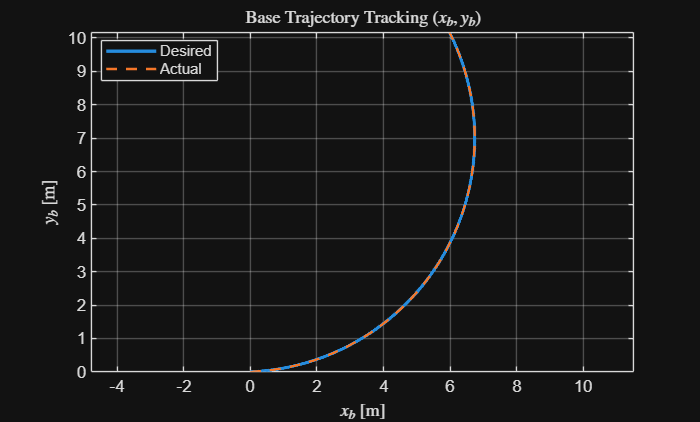


%% Simulation horizon and reference-grid resolution
Tf     = 20;        % [s] total time
dt_ref = 1e-3;      % [s] small step for reference integration

%% Build kinematically consistent reference trajectory for q_d(t)
ref = mm_build_reference_trajectory(phys, Tf, dt_ref);

%% Dimensions
nq = 8;
ne = 5;
nx = nq + ne;

%% Controller gains in eta-space
Kp = diag([60 60 50 50 50]);
Kd = diag([15 15 12 12 12]);    % eta = [theta_r; theta_l; theta_1; theta_2; theta_3]


%% Initial state: start on the reference trajectory at t = 0
q0       = ref.q(1, :).';                  % [x_b0; y_b0; theta_m0; ...]
[eta_dot0, ~] = mm_desired_eta_law(0, phys);  % desired eta_dot at t=0

X0 = [q0; eta_dot0];
% size(X0)
% X0 = ones(13, 1)*0.5;
%% Control law handle
u_fun = @(t, q, eta_dot) mm_eta_tracking_controller_ct( ...
    t, q, eta_dot, phys, ref, Kp, Kd);

%% ODE wrapper
ode_fun = @(t, X) mm_forward_dynamics_reduced(t, X, u_fun);

%% Simulate
tspan = [0 Tf];
opts  = odeset('RelTol',1e-6, 'AbsTol',1e-8);

[t, X] = ode45(ode_fun, tspan, X0, opts);

%% Extract states
q_hist       = X(:, 1:nq);
eta_dot_hist = X(:, nq+1:nx); %#ok<NASGU>

x_b     = q_hist(:,1);
y_b     = q_hist(:,2);
theta_m = q_hist(:,3);
theta1  = q_hist(:,6);
theta2  = q_hist(:,7);
theta3  = q_hist(:,8);

%% Desired trajectory on same time grid
N = numel(t);
q_d_hist  = zeros(N, nq);

for k = 1:N
    [q_dk, ~, ~, ~, ~] = mm_desired_trajectory_from_ref(t(k), phys, ref);
    q_d_hist(k,:) = q_dk.';
end

x_b_d     = q_d_hist(:,1);
y_b_d     = q_d_hist(:,2);
theta_m_d = q_d_hist(:,3);
theta1_d  = q_d_hist(:,6);
theta2_d  = q_d_hist(:,7);
theta3_d  = q_d_hist(:,8);

%% =====================  STATE TRACKING PLOTS  =====================

% (1) Base trajectory (x_b, y_b)
figure;
plot(x_b_d, y_b_d, 'LineWidth', 2); hold on;
plot(x_b,   y_b,   '--', 'LineWidth', 1.5);
xlabel('$x_b$ [m]','Interpreter','latex');
ylabel('$y_b$ [m]','Interpreter','latex');
legend('Desired','Actual','Location','best');
title('Base Trajectory Tracking $(x_b,y_b)$','Interpreter','latex');
axis equal; grid on;

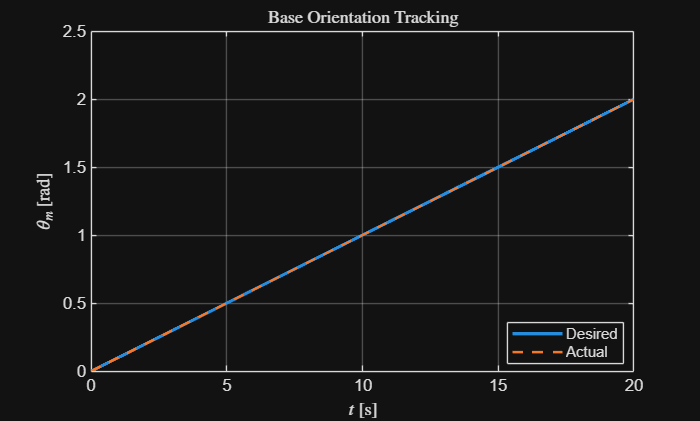


% (2) Base orientation theta_m
figure;
plot(t, theta_m_d, 'LineWidth', 2); hold on;
plot(t, theta_m,   '--', 'LineWidth', 1.5);
xlabel('$t$ [s]','Interpreter','latex');
ylabel('$\theta_m$ [rad]','Interpreter','latex');
legend('Desired','Actual','Location','best');
title('Base Orientation Tracking','Interpreter','latex');
grid on;

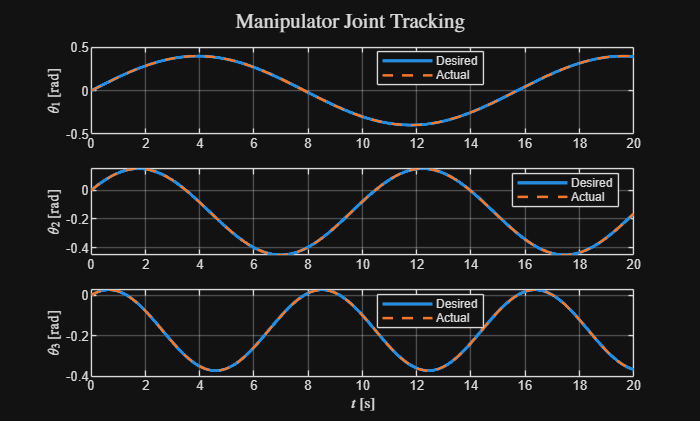


% (3) Manipulator joint tracking
figure;
subplot(3,1,1);
plot(t, theta1_d, 'LineWidth', 2); hold on;
plot(t, theta1,   '--', 'LineWidth', 1.5);
ylabel('$\theta_1$ [rad]','Interpreter','latex');
legend('Desired','Actual','Location','best');
grid on;

subplot(3,1,2);
plot(t, theta2_d, 'LineWidth', 2); hold on;
plot(t, theta2,   '--', 'LineWidth', 1.5);
ylabel('$\theta_2$ [rad]','Interpreter','latex');
legend('Desired','Actual','Location','best');
grid on;

subplot(3,1,3);
plot(t, theta3_d, 'LineWidth', 2); hold on;
plot(t, theta3,   '--', 'LineWidth', 1.5);
xlabel('$t$ [s]','Interpreter','latex');
ylabel('$\theta_3$ [rad]','Interpreter','latex');
legend('Desired','Actual','Location','best');
grid on;

sgtitle('Manipulator Joint Tracking','Interpreter','latex');

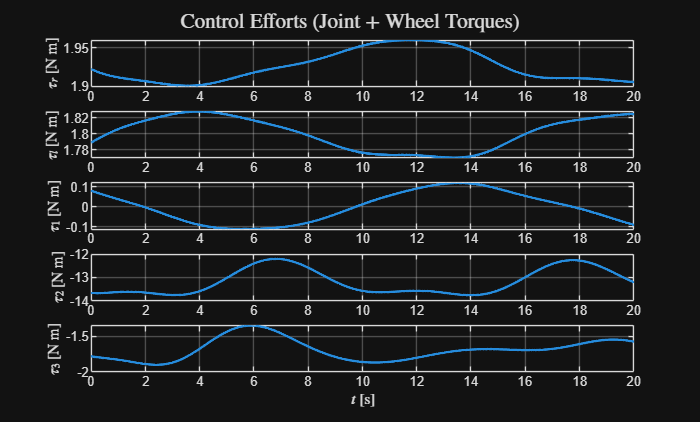


%% =====================  CONTROL EFFORT PLOTS  =====================
global T_LOG U_LOG

% Sort logs by time (ODE45 can call controller in non-monotonic order)
[T_ctrl, idx] = sort(T_LOG);
U_ctrl        = U_LOG(idx, :);

tau_r = U_ctrl(:,1);
tau_l = U_ctrl(:,2);
tau_1 = U_ctrl(:,3);
tau_2 = U_ctrl(:,4);
tau_3 = U_ctrl(:,5);

figure;
subplot(5,1,1);
plot(T_ctrl, tau_r, 'LineWidth', 1.5);
ylabel('$\tau_r$ [N m]','Interpreter','latex');
grid on;

subplot(5,1,2);
plot(T_ctrl, tau_l, 'LineWidth', 1.5);
ylabel('$\tau_l$ [N m]','Interpreter','latex');
grid on;

subplot(5,1,3);
plot(T_ctrl, tau_1, 'LineWidth', 1.5);
ylabel('$\tau_1$ [N m]','Interpreter','latex');
grid on;

subplot(5,1,4);
plot(T_ctrl, tau_2, 'LineWidth', 1.5);
ylabel('$\tau_2$ [N m]','Interpreter','latex');
grid on;

subplot(5,1,5);
plot(T_ctrl, tau_3, 'LineWidth', 1.5);
ylabel('$\tau_3$ [N m]','Interpreter','latex');
xlabel('$t$ [s]','Interpreter','latex');
grid on;

sgtitle('Control Efforts (Joint + Wheel Torques)','Interpreter','latex');